% Load lidar data FRom the mat file
data=load("lidarPointClouds.mat");
lidarPointClouds=data.lidarPointClouds;

% Display lidarPointCloud data
head(lidarPointClouds)

ans = 8×1 timetable
        Time            PointCloud   
    _____________    ________________

    23:46:10.5115    [1×1 pointCloud]
    23:46:10.6115    [1×1 pointCloud]
    23:46:10.7116    [1×1 pointCloud]
    23:46:10.8117    [1×1 pointCloud]
    23:46:10.9118    [1×1 pointCloud]
    23:46:11.0119    [1×1 pointCloud]
    23:46:11.1120    [1×1 pointCloud]
    23:46:11.2120    [1×1 pointCloud]


% Load the GPS sequence mat file 
data=load("gpsSequence.mat");
gpsSequence=data.gpsSequence;

% Display gpsSequence data
head(gpsSequence)

ans = 8×3 timetable
        Time         Latitude    Longitude    Altitude
    _____________    ________    _________    ________

    23:46:11.4563      37.4       -122.11      -42.5  
    23:46:12.4563      37.4       -122.11      -42.5  
    23:46:13.4565      37.4       -122.11      -42.5  
    23:46:14.4455      37.4       -122.11      -42.5  
    23:46:15.4455      37.4       -122.11      -42.5  
    23:46:16.4567      37.4       -122.11      -42.5  
    23:46:17.4573      37.4       -122.11      -42.5  
    23:46:18.4656      37.4       -122.11      -42.5  


% Load IMU orientation readings from the mat file
data=load("imuOrientations.mat");
imuOrientations=data.imuOrientations;

% Convert imuOrientations readings to quaternion type
imuOrientations=convertvars(imuOrientations,'Orientation','quaternion');

% Display imuOrientations readings 
head(imuOrientations)

ans = 8×1 timetable
        Time           Orientation   
    _____________    ________________

    23:46:11.4570    [1×1 quaternion]
    23:46:11.4605    [1×1 quaternion]
    23:46:11.4620    [1×1 quaternion]
    23:46:11.4655    [1×1 quaternion]
    23:46:11.4670    [1×1 quaternion]
    23:46:11.4705    [1×1 quaternion]
    23:46:11.4720    [1×1 quaternion]
    23:46:11.4755    [1×1 quaternion]


% Compute the frame duration (length of time in fixed-length scale)
lidarframeduration=median(diff(lidarPointClouds.Time));
gpsSequenceframeduartion=median(diff(gpsSequence.Time));
imuOrientationsframeduration=median(diff(imuOrientations.Time));

% Adjust dispaly format to seconds
lidarframeduration.Format='s';
gpsSequenceframeduration.Format='s';
imuOrientationsframeduration.Format='s';

% Compute the frame rate (average update rate of the input signal)
lidarrate=1/seconds(lidarframeduration);
gpsSequencerate=1/seconds(gpsSequenceframeduartion);
imuOrientationsrate=1/seconds(imuOrientationsframeduration);

% Display frame rates by using fprintf which writes data to text file
fprintf('Lidar: %s, %3.1f Hz/n',char(lidarframeduration),lidarrate)

Lidar: 0.10008 sec, 10.0 Hz/n

fprintf('GPS: %s, %3.1f Hz/n',char(gpsSequenceframeduartion),gpsSequencerate)

GPS: 00:00:01, 1.0 Hz/n

fprintf('IMU: %s, %3.1f Hz/n',char(imuOrientationsframeduration),imuOrientationsrate)

IMU: 0.002493 sec, 401.1 Hz/n

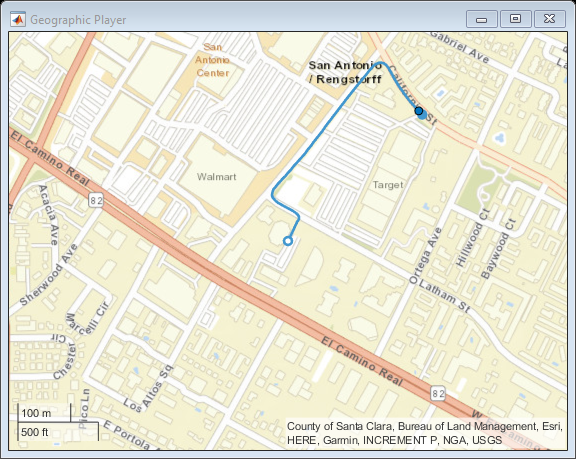

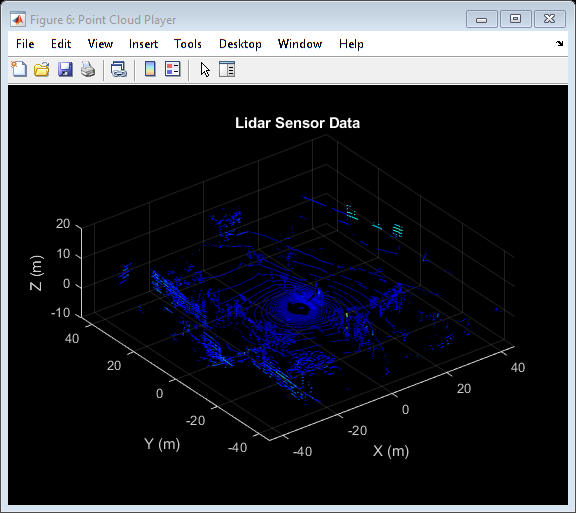

% Create a geoplayer to visualize streaming geographic map data
latCenter = gpsSequence.Latitude(1);
lonCenter = gpsSequence.Longitude(1);
zoomLevel = 16;

gpsPlayer = geoplayer(latCenter, lonCenter, zoomLevel);

% Plot the full route
plotRoute(gpsPlayer, gpsSequence.Latitude, gpsSequence.Longitude);

% Determine limits for the player
xlimits = [-45 45]; % meters
ylimits = [-45 45]; % meters
zlimits = [-10 20]; % meters

% Create a pcplayer to visualize streaming point clouds from lidar sensor
lidarPlayer = pcplayer(xlimits, ylimits, zlimits);

% Customize player axes labels
xlabel(lidarPlayer.Axes, 'X (m)')
ylabel(lidarPlayer.Axes, 'Y (m)')
zlabel(lidarPlayer.Axes, 'Z (m)')

title(lidarPlayer.Axes, 'Lidar Sensor Data')

% Align players on screen to view gps player and lidar player paralelly on the screen 
helperAlignPlayers({gpsPlayer, lidarPlayer});

% Outer loop over GPS readings (slower signal)
for g = 1 : height(gpsSequence)-1

    % Extract geographic coordinates from timetable
    latitude  = gpsSequence.Latitude(g);
    longitude = gpsSequence.Longitude(g);

    % Update current position in GPS display
    plotPosition(gpsPlayer, latitude, longitude);

    % Compute the time span between the current and next GPS reading
    timeSpan = timerange(gpsSequence.Time(g), gpsSequence.Time(g+1));

    % Extract the lidar frames recorded during this time span
    lidarFrames = lidarPointClouds(timeSpan, :);

    % Inner loop over lidar readings (faster signal)
    for l = 1 : height(lidarFrames)

        % Extract point cloud
        ptCloud = lidarFrames.PointCloud(l);

        % Update lidar display
        view(lidarPlayer, ptCloud);

        % Pause to slow down the display
        pause(0.01)
    end
end

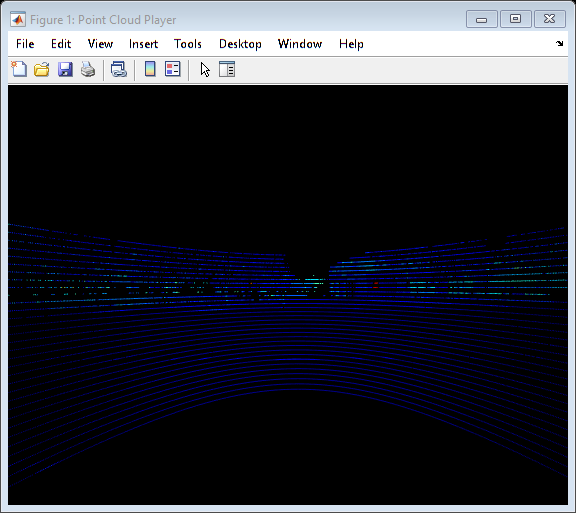

% Build a map 

% Hide players
hide(gpsPlayer)
hide(lidarPlayer)

% Select a frame of lidar data to demonstrate registration workflow
frameNum = 600;
ptCloud = lidarPointClouds.PointCloud(frameNum);

% Display and rotate ego view to show lidar data
helperVisualizeEgoView(ptCloud);

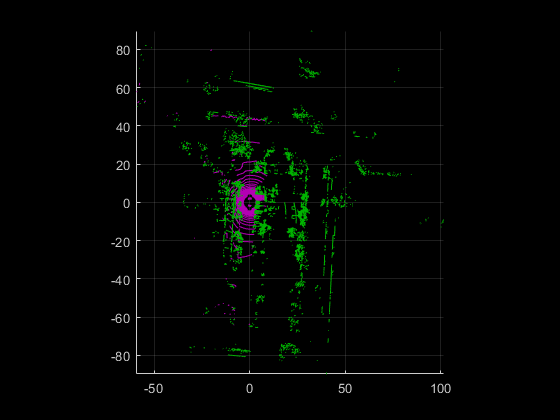


% by taking the two point clouds corresponding to nearby lidar scans and to
% speed up the processing and accumulate enough motion between scans, use
% of every tenth scan is taken.
skipfrmaes=10;
frameNum=100;
fixed=lidarPointClouds.PointCloud(frameNum);
moving=lidarPointClouds.PointCloud(frameNum+skipfrmaes);

% Prior to registration, process the point cloud so as to retain structures in the point cloud that are distinctive. 
% These pre-processing steps include the following: 
% * Detect and remove the ground plane * Detect and remove ego-vehicle

fixedProcessed  = helperProcessPointCloud(fixed);
movingProcessed = helperProcessPointCloud(moving);

% Display the raw and processed point clouds in top-view. Magenta points were removed during processing. 
% These points correspond to the ground plane and ego vehicle.

hFigFixed = figure;
pcshowpair(fixed, fixedProcessed)
view(2);                            % Adjust view to show top-view

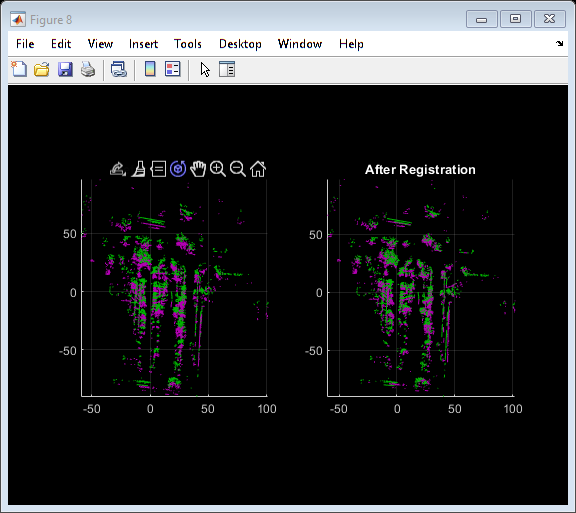


helperMakeFigurePublishFriendly(hFigFixed);

% Downsample the point clouds prior to registration. Downsampling improves
% both registration accuracy and algorithm speed.
downsamplePercent = 0.1;
fixedDownsampled  = pcdownsample(fixedProcessed, 'random', downsamplePercent);
movingDownsampled = pcdownsample(movingProcessed, 'random', downsamplePercent);

% By using NDT tech. the registration process is done.
regGridStep = 5;
tform = pcregisterndt(movingDownsampled, fixedDownsampled, regGridStep);

movingReg = pctransform(movingProcessed, tform);

% Visualize alignment in top-view before and after registration
hFigAlign = figure;

% by using pcshowpair we can visualize difference between two point clouds
subplot(121)
pcshowpair(movingProcessed, fixedProcessed)
title('Before Registration')
view(2)

subplot(122)
pcshowpair(movingReg, fixedProcessed)
title('After Registration')
view(2)

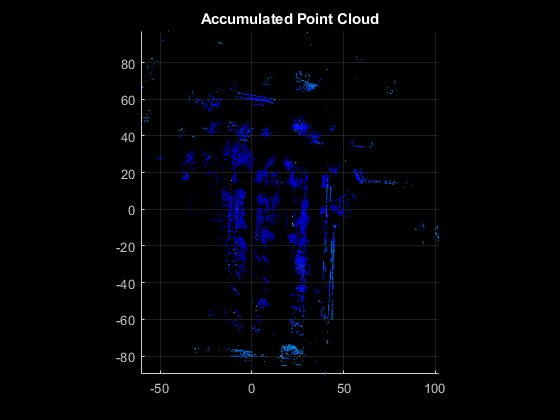


helperMakeFigurePublishFriendly(hFigAlign);

% Notice that the point clouds are well-aligned after registration. 
% Even though the point clouds are closely aligned, the alignment is still not perfect.
%Next, merge the point clouds using pcmerge.

mergeGridStep = 0.5;
ptCloudAccum = pcmerge(fixedProcessed, movingReg, mergeGridStep);

hFigAccum = figure;
pcshow(ptCloudAccum)
title('Accumulated Point Cloud')
view(2)


helperMakeFigurePublishFriendly(hFigAccum);


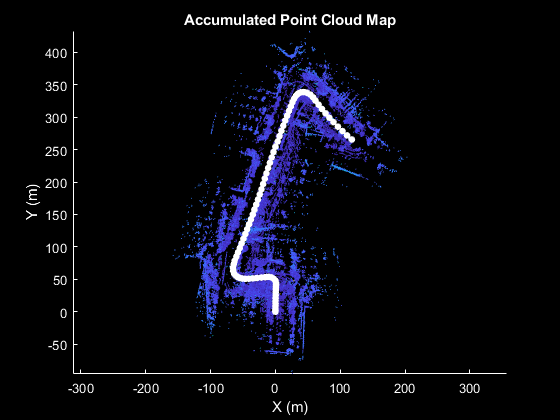

% Create a map builder object
mapBuilder = helperLidarMapBuilder('DownsamplePercent', downsamplePercent);

% Set random number seed
rng(0);

closeDisplay = false;
numFrames    = height(lidarPointClouds);

tform = rigid3d;
for n = 1 : skipfrmaes : numFrames - skipfrmaes

    % Get the nth point cloud
    ptCloud = lidarPointClouds.PointCloud(n);

    % Use transformation from previous iteration as initial estimate for
    % current iteration of point cloud registration. (constant velocity)
    initTform = tform;

    % Update map using the point cloud
    tform = updateMap(mapBuilder, ptCloud, initTform);

    % Update map display
    updateDisplay(mapBuilder,closeDisplay);
end


% Use the recorded GPS readings as a ground truth trajectory, to visually evaluate the quality of the built map.
% First convert the GPS readings (latitude, longitude, altitude) to a local coordinate system. 
% Select a local coordinate system that coincides with the origin of the first point cloud in the sequence


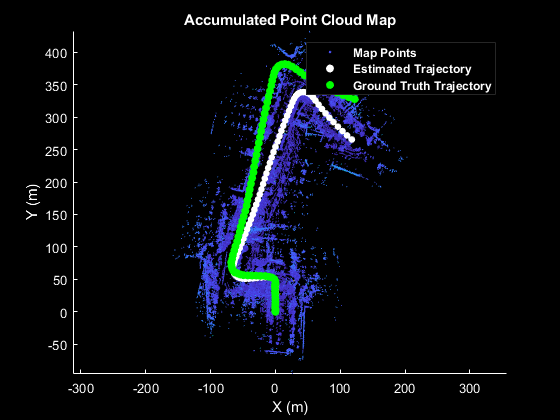


% Convert the GPS coordinates to local Cartesian East-North-Up coordinates using the latlon2local function.

% Select reference point as first GPS reading
origin = [gpsSequence.Latitude(1), gpsSequence.Longitude(1), gpsSequence.Altitude(1)];

% Convert GPS readings to a local East-North-Up coordinate system
[xEast, yNorth, zUp] = latlon2local(gpsSequence.Latitude, gpsSequence.Longitude, ...
    gpsSequence.Altitude, origin);


% Rotate the Cartesian coordinates so that the local coordinate system is aligned with the first lidar sensor coordinates. 
% Since the exact mounting configuration of the lidar and GPS on the vehicle are not known, they are estimated.
% Estimate rough orientation at start of trajectory to align local ENU
% system with lidar coordinate system
theta = median(atan2d(yNorth(1:15), xEast(1:15)));

R = [ cosd(90-theta) sind(90-theta) 0;
     -sind(90-theta) cosd(90-theta) 0;
     0               0              1];

% Rotate ENU coordinates to align with lidar coordinate system
groundTruthTrajectory = [xEast, yNorth, zUp] * R;

% Superimpose the ground truth trajectory on the built map.

hold(mapBuilder.Axes, 'on')
scatter(mapBuilder.Axes, groundTruthTrajectory(:,1), groundTruthTrajectory(:,2), ...
    'green','filled');

helperAddLegend(mapBuilder.Axes, ...
    {'Map Points', 'Estimated Trajectory', 'Ground Truth Trajectory'});


% The trajectory estimated using point cloud registration alone can drift for a number of reasons:
% Noisy scans from the sensor without sufficient overlap
% Absence of strong enough features, for example, near long roads
% Inaccurate initial transformation, especially when rotation is significant.


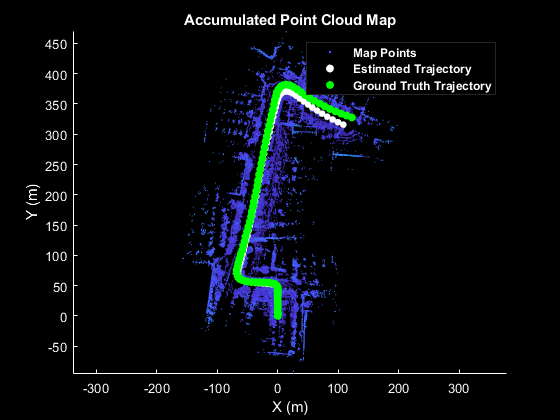

% Use the IMU readings to provide a better initial estimate for registration.

% Reset the map builder to clear previously built map
reset(mapBuilder);

% Set random number seed
rng(0);

initTform = rigid3d;
for n = 1 : skipfrmaes : numFrames - skipfrmaes

    % Get the nth point cloud
    ptCloud = lidarPointClouds.PointCloud(n);

    if n > 1
        % Since IMU sensor reports readings at a much faster rate, gather
        % IMU readings reported since the last lidar scan.
        prevTime = lidarPointClouds.Time(n - skipfrmaes);
        currTime = lidarPointClouds.Time(n);
        timeSinceScan = timerange(prevTime, currTime);

        imuReadings = imuOrientations(timeSinceScan, 'Orientation');

        % Form an initial estimate using IMU readings
        initTform = helperComputeInitialEstimateFromIMU(imuReadings, tform);
    end

    % Update map using the point cloud
    tform = updateMap(mapBuilder, ptCloud, initTform);

    % Update map display
    updateDisplay(mapBuilder, closeDisplay);
end


% Superimpose ground truth trajectory on new map
hold(mapBuilder.Axes, 'on')
scatter(mapBuilder.Axes, groundTruthTrajectory(:,1), groundTruthTrajectory(:,2), ...
    'green','filled');

helperAddLegend(mapBuilder.Axes, ...
    {'Map Points', 'Estimated Trajectory', 'Ground Truth Trajectory'});

% Supporting function for helperalign players 

function helperAlignPlayers(players)

validateattributes(players, {'cell'}, {'vector'});

hasAxes = cellfun(@(p)isprop(p,'Axes'),players,'UniformOutput', true);
if ~all(hasAxes)
    error('Expected all viewers to have an Axes property');
end

screenSize   = get(groot, 'ScreenSize');
screenMargin = [50, 100];

playerSizes = cellfun(@getPlayerSize, players, 'UniformOutput', false);
playerSizes = cell2mat(playerSizes);

maxHeightInSet = max(playerSizes(1:3:end));

% Arrange players vertically so that the tallest player is 100 pixels from the top.
location = round([screenMargin(1), screenSize(4)-screenMargin(2)-maxHeightInSet]);
for n = 1 : numel(players)
    player = players{n};

    hFig = ancestor(player.Axes, 'figure');
    hFig.OuterPosition(1:2) = location;

    % Set up next location by going right
    location = location + [50+hFig.OuterPosition(3), 0];
end

    function sz = getPlayerSize(viewer)

        % Get the parent figure container
        h = ancestor(viewer.Axes, 'figure');

        sz = h.OuterPosition(3:4);
    end
end

% helperVisualizeEgoView visualizes point cloud data in the ego perspective by rotating about the center.
function player = helperVisualizeEgoView(ptCloud)

% Create a pcplayer object
xlimits = ptCloud.XLimits;
ylimits = ptCloud.YLimits;
zlimits = ptCloud.ZLimits;

player = pcplayer(xlimits, ylimits, zlimits);

% Turn off axes lines
axis(player.Axes, 'off');

% Set up camera to show ego view
camproj(player.Axes, 'perspective');
camva(player.Axes, 90);
campos(player.Axes, [0 0 0]);
camtarget(player.Axes, [-1 0 0]);

% Set up a transformation to rotate by 5 degrees
theta = 5;
R = [ cosd(theta) sind(theta) 0 0
     -sind(theta) cosd(theta) 0 0
      0          0            1 0
      0          0            0 1];
rotateByTheta = rigid3d(R);

for n = 0 : theta : 359
    % Rotate point cloud by theta
    ptCloud = pctransform(ptCloud, rotateByTheta);

    % Display point cloud
    view(player, ptCloud);

    pause(0.05)
end
end

% helperProcessPointCloud processes a point cloud by removing points belonging to the ground plane or ego vehicle.
function ptCloudProcessed = helperProcessPointCloud(ptCloud)

% Check if the point cloud is organized
isOrganized = ~ismatrix(ptCloud.Location);

% If the point cloud is organized, use range-based flood fill algorithm
% (segmentGroundFromLidarData). Otherwise, use plane fitting.
groundSegmentationMethods = ["planefit", "rangefloodfill"];
method = groundSegmentationMethods(isOrganized+1);

if method == "planefit"
    % Segment ground as the dominant plane, with reference normal vector
    % pointing in positive z-direction, using pcfitplane. For organized
    % point clouds, consider using segmentGroundFromLidarData instead.
    maxDistance    = 0.4;       % meters
    maxAngDistance = 5;         % degrees
    refVector      = [0, 0, 1]; % z-direction

    [~,groundIndices] = pcfitplane(ptCloud, maxDistance, refVector, maxAngDistance);
elseif method == "rangefloodfill"
    % Segment ground using range-based flood fill.
    groundIndices = segmentGroundFromLidarData(ptCloud);
else
    error("Expected method to be 'planefit' or 'rangefloodfill'")
end

% Segment ego vehicle as points within a given radius of sensor
sensorLocation = [0, 0, 0];
radius         = 3.5;

egoIndices  = findNeighborsInRadius(ptCloud, sensorLocation, radius);

% Remove points belonging to ground or ego vehicle
ptsToKeep = true(ptCloud.Count, 1);
ptsToKeep(groundIndices) = false;
ptsToKeep(egoIndices)    = false;

% If the point cloud is organized, retain organized structure
if isOrganized
    ptCloudProcessed = select(ptCloud, find(ptsToKeep), 'OutputSize', 'full');
else
    ptCloudProcessed = select(ptCloud, find(ptsToKeep));
end
end

% helperMakeFigurePublishFriendly adjusts figures so that screenshot captured by publish is correct.
function helperMakeFigurePublishFriendly(hFig)

if ~isempty(hFig) && isvalid(hFig)
    hFig.HandleVisibility = 'callback';
end

end

% helperAddLegend adds a legend to the axes.
function helperAddLegend(hAx, labels)

% Add a legend to the axes
hLegend = legend(hAx, labels{:});

% Set text color and font weight
hLegend.TextColor  = [1 1 1];
hLegend.FontWeight = 'bold';
end

% helperComputeInitialEstimateFromIMU estimates an initial transformation for NDT using IMU orientation readings and previously estimated transformation.

function tform = helperComputeInitialEstimateFromIMU(imuReadings, prevTform)

% Initialize transformation using previously estimated transform
tform = prevTform;

% If no IMU readings are available, return
if height(imuReadings) <= 1
    return;
end

% IMU orientation readings are reported as quaternions representing the
% rotational offset to the body frame. Compute the orientation change
% between the first and last reported IMU orientations during the interval
% of the lidar scan.
q1 = imuReadings.Orientation(1);
q2 = imuReadings.Orientation(end);

% Compute rotational offset between first and last IMU reading by
%   - Rotating from q2 frame to body frame
%   - Rotating from body frame to q1 frame
q = q1 * conj(q2);

% Convert to Euler angles
yawPitchRoll = euler(q, 'ZYX', 'point');

% Discard pitch and roll angle estimates. Use only heading angle estimate
% from IMU orientation.
yawPitchRoll(2:3) = 0;

% Convert back to rotation matrix
q = quaternion(yawPitchRoll, 'euler', 'ZYX', 'point');
R = rotmat(q, 'point');

% Use computed rotation
tform.T(1:3, 1:3) = R';
end